clearvars; close all; clc;

% Load file information
% folder_path = 'D:\Dropbox\Data\8-5-20 fixed neurons glut4 and vglut\';
% cd(folder_path);
% data_path = 'D:\Dropbox\Data\8-5-20 fixed neurons glut4 and vglut\Analysis\toleranced\';
% step_size = 0.02;
% frame_exposure = 0.04;
% ruler_name = 'cell_10_dz_20_r_scan.tif';
% image_name ='cell_10_dz_20_r_0.tif';
folder_path = 'D:\Dropbox\Data\8-3-20 2-color neurons\glut4_actual\';
cd(folder_path);
data_path = [folder_path,'\Analysis\toleranced\'];
step_size = 0.02;
frame_exposure = 0.04;
ruler_name = 'cell_1_dz_20_r_scan.tif';
image_name ='cell_1_dz_20_r_2_1.tif';
% [image_name = ('*_dz_*');
str_ind = strfind(ruler_name, 'dz_');
str_end = strfind(ruler_name, '_r_');
step_size = str2num(ruler_name(str_ind+3:str_end-1))/1000;
data_name = [image_name(1:end-4),'_dast_tol.mat'];
ruler_image = readtiff(ruler_name);
image = readtiff(image_name);

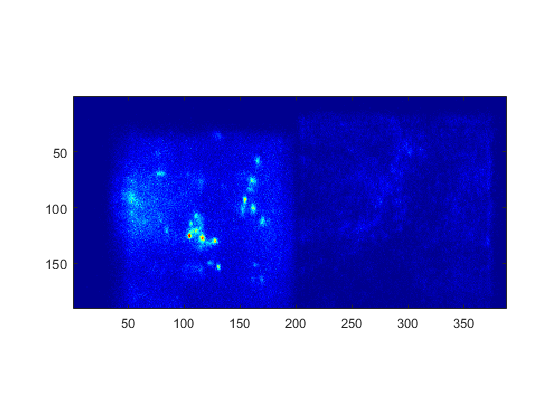

%Visualize Information
imagesc(ruler_image(:,:,1))
axis image

h = imagesc(ruler_image(:,:,1),[3 200])

h =   Image with properties:

           CData: [190×388 double]
    CDataMapping: 'scaled'

  Show all properties


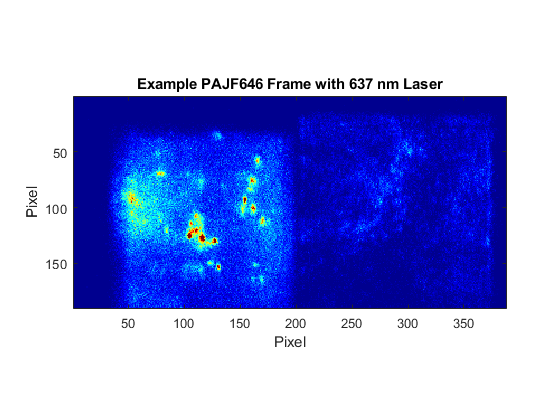

xlabel("Pixel")
ylabel("Pixel")
colormap('jet')
title("Example PAJF646 Frame with 637 nm Laser")
axis image

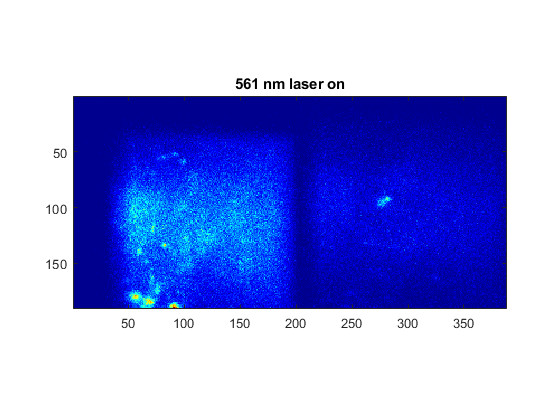

% gif('Example of a ruler.gif','DelayTime',0.04)
% for i = 2:numel(ruler_image(1,1,:))
%     set(h,"CData",ruler_image(:,:,i))
%     gif()
% end




imagesc(image(:,:,1))
axis image
title('561 nm laser on')

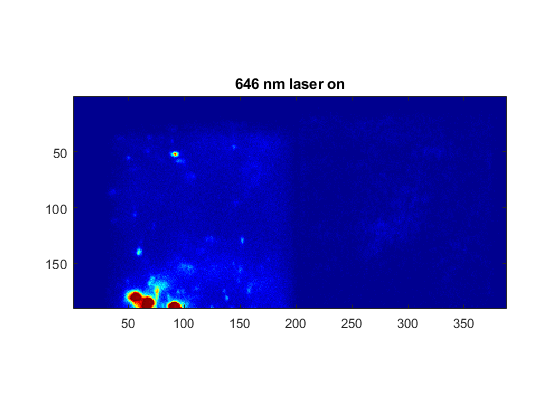

imagesc(image(:,:,2))
title('646 nm laser on')
axis image


channel_split = 200; % X position split in pixels
channel_split_end = 375; % end of channel cropping
channel_vertical_crop_start = 15;
[m,n,o] = size(ruler_image)

m = 190

n = 388

o = 200

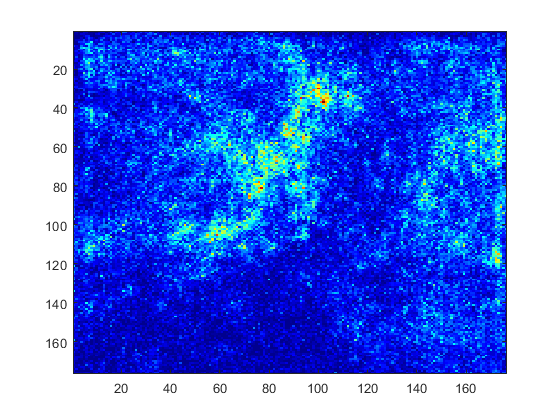

channel_vertical_crop_stop = m;
imagesc(ruler_image(channel_vertical_crop_start:channel_vertical_crop_stop,channel_split:channel_split_end,1))

sub_ruler_image = ruler_image(channel_vertical_crop_start:channel_vertical_crop_stop,channel_split:channel_split_end,:);

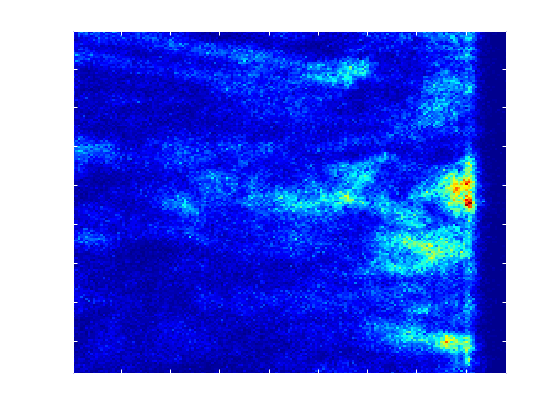

h =   Image with properties:

           CData: [176×176 double]
    CDataMapping: 'scaled'

  Show all properties


laser_images = image(channel_vertical_crop_start:channel_vertical_crop_stop,channel_split:channel_split_end,2:2:end);
h=imagesc(sub_ruler_image(:,:,1))

% gif('Example of a cropped ruler.gif','DelayTime',0.04)
% for i = 2:numel(sub_ruler_image(1,1,:))
%     set(h,"CData",sub_ruler_image(:,:,i))
%     gif()
% end

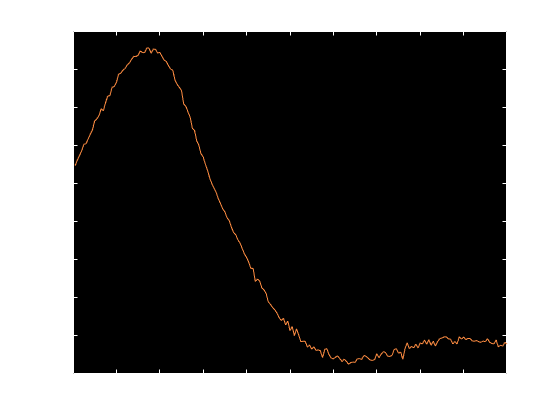

% Build ruler for subsequent measurment
[m,n,o] = size(sub_ruler_image);

C = zeros(o,1);
for i = 1:o
    C(i) = corr2(sub_ruler_image(:,:,i),laser_images(:,:,40));
end
plot(C)
xlabel('Sorted bleedthrough image index')
ylabel('2D X-Correlation')
title("Correlation values")

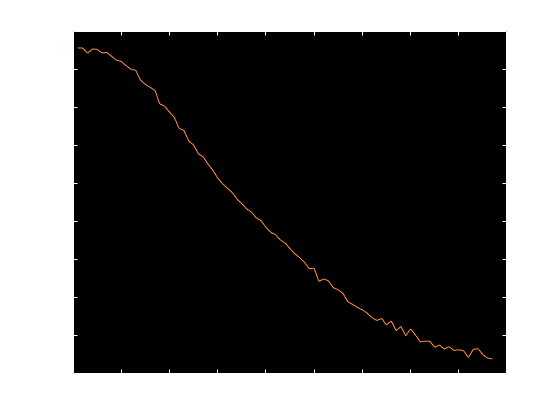



sub_C  = C(20:120);
max_corr = find(sub_C == max(sub_C));
min_corr = find(sub_C == min(sub_C));
plot(C(19+max_corr:19+min_corr));
title('Subset of Correlation values to ensure 1 slope')

ruler = sub_ruler_image(:,:,19+max_corr:19+min_corr);

% Parse image data to grab laser_sections
% Remember red channel is the even frames
laser_images = image(channel_vertical_crop_start:channel_vertical_crop_stop,channel_split:channel_split_end,2:2:end);

indexes = get_index_from_ruler(sub_ruler_image,laser_images);
indexes_raw = indexes;

% indexes_quartile_average = get_index_from_quartile_average(ruler,laser_images);

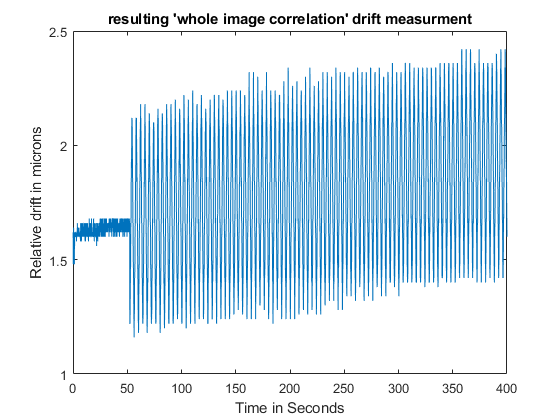

% Visualize the result
plot((1:numel(indexes))*2*frame_exposure,indexes_raw*step_size)
hold on
% plot([5250 5600, 5600, 5250, 5250], [0.08,0.08, 0.21,0.21,0.08] ,'r')
hold off
title("resulting 'whole image correlation' drift measurment")
xlabel('Time in Seconds')
ylabel('Relative drift in microns')

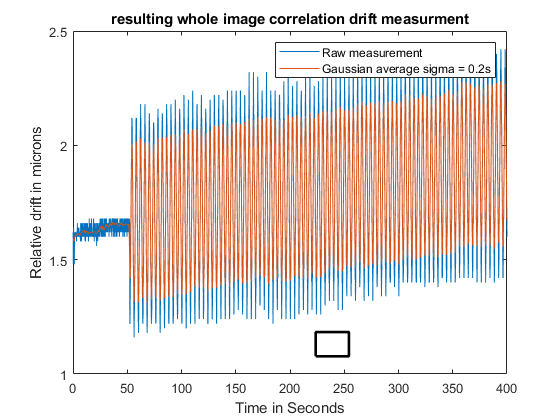


% Visualize the result
plot((1:numel(indexes))*2*frame_exposure,indexes_raw*step_size)

hold on
plot((1:numel(indexes))*2*frame_exposure,gausssmooth(indexes_raw, 5,10)*step_size)
% plot([5250 5600, 5600, 5250, 5250], [0.08,0.08, 0.21,0.21,0.08] ,'r')
plot([223.7 254.3, 254.3, 223.7, 223.7], [1.0774,1.0774, 1.1835,1.1835,1.0774] ,'k','LineWidth',2)
hold off
title("resulting whole image correlation drift measurment")
xlabel('Time in Seconds')
ylabel('Relative drift in microns')
legend('Raw measurement',['Gaussian average sigma = ',num2str(5*frame_exposure),'s'])% Visualize the result

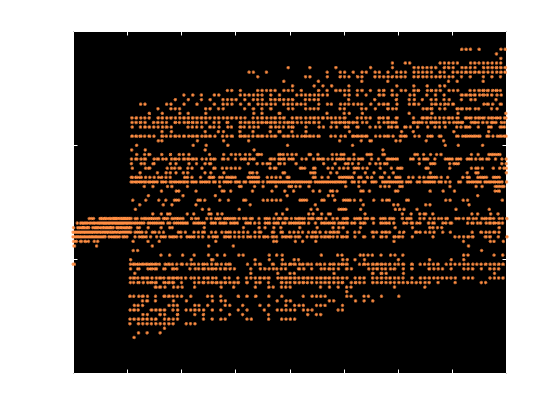

%Load localization data and start correcting
load([data_path,data_name]);
% z_correction = spline((2:2:2*numel(indexes_raw)), gausssmooth(indexes_raw, 5,10),cdata.red.framenumber)*step_size;
z_correction = spline((2:2:2*numel(indexes_raw)), indexes_raw,cdata.red.framenumber)*step_size;
plot(cdata.red.framenumber*frame_exposure,z_correction,'.')
xlabel('Time in s')
ylabel('Correction in um')
title('Resulting z correction')

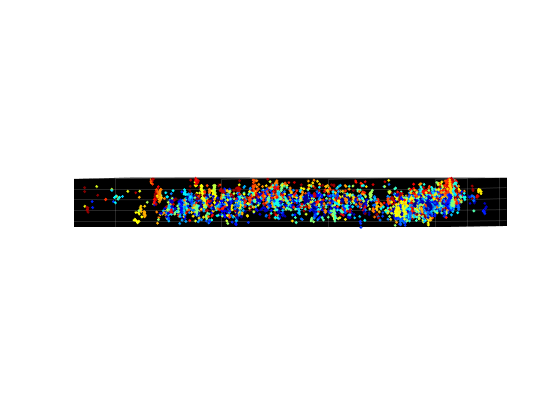

ind = cdata.red.zf < 0.5;
% subplot(2,1,1)
s = scatter3(cdata.red.xf(ind),cdata.red.yf(ind),-(cdata.red.zf(ind)-z_correction(ind)),3,cdata.red.framenumber(ind));
s.MarkerFaceColor = s.MarkerEdgeColor;
whitebg([0 0 0])
title('Scatter Plot of corrected localization')
colormap('jet')
axis equal

%subplot(2,1,2)
s = scatter3(cdata.red.xf(ind),cdata.red.yf(ind),-cdata.red.zf(ind),3,cdata.red.framenumber(ind))

s =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 3
          LineWidth: 0.5000
              XData: [1×7030 double]
              YData: [1×7030 double]
              ZData: [1×7030 double]
              CData: [7030×1 double]

  Show all properties


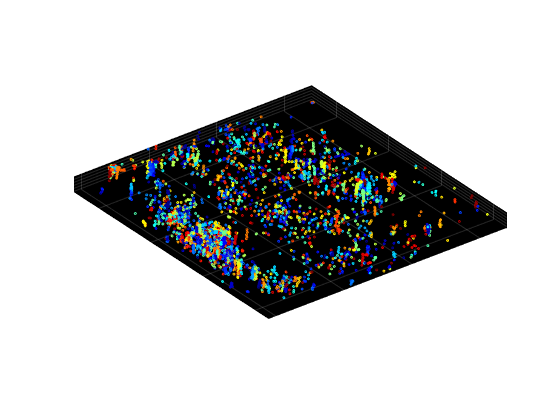

axis equal

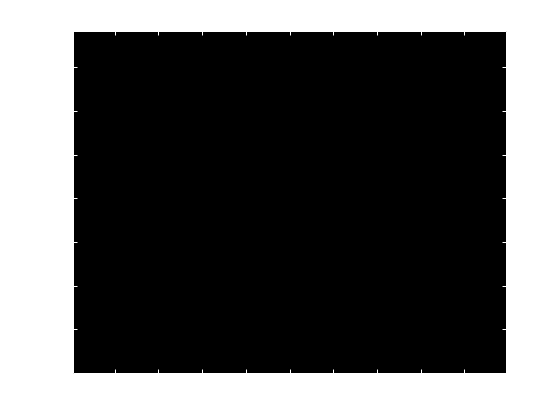

histogram(cdata.red.zf(ind),100)
title('Scatter Plot of corrected localization')
colormap('jet')
axis equal
whitebg([0 0 0])

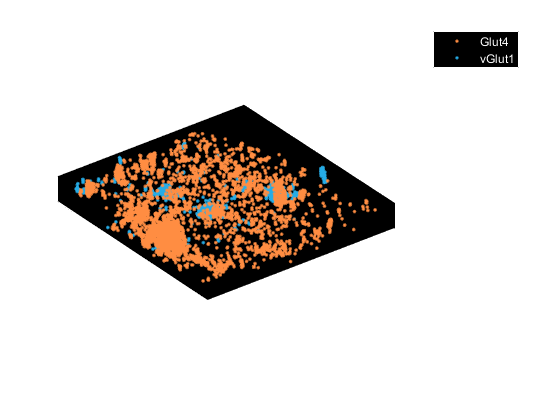

close all
ind_o = abs(cdata.orange.zf) < 0.51;
vector = xy_feature(cdata.orange.xf/cal.q,cdata.orange.yf/cal.q);
xf = cal.q*cal.o2rx.'*vector.';
yf = cal.q*cal.o2ry.'*vector.';
markerSize = 4;
plot3(cdata.red.xf(ind),cdata.red.yf(ind),cdata.red.zf(ind) - z_correction(ind),'.');
zf = cdata.orange.zf - spline((2:2:2*numel(indexes_raw)), gausssmooth(indexes_raw, 5,10),cdata.orange.framenumber)*step_size;
zf = cdata.orange.zf - spline((2:2:2*numel(indexes_raw)), indexes_raw, cdata.orange.framenumber)*step_size;
hold on
plot3(xf(ind_o),yf(ind_o),zf(ind_o),'.')


colormap('jet')
legend('Glut4','vGlut1')

axis equal
% xlim([7 12])
% midz = (max(zf) + min(zf))/2;
% ylim([midz - 2.5, midz + 2.5])
% view([0, 00])
xlabel('Microns')
ylabel('Microns')
zlabel('Axial in microns')
hold off

% xlim([12.5 16.5])
% ylim([9.5 13.5])
% midz = 0;
% zlim([midz - 2, midz + 2])
%gif('fixed_neruon_vglut_glut4_cell10_.gif','DelayTime', 0.03)
% clear M
% M(1) = getframe(gcf);
% view([0 30])
% for i = 1:1:359
%     view([i,30])
%     M(numel(M)+1) = getframe(gcf);
% end
% movie2gif(M,'full_rotating_vglut_glut4.gif','DelayTime',0.03,'LoopCount',Inf)




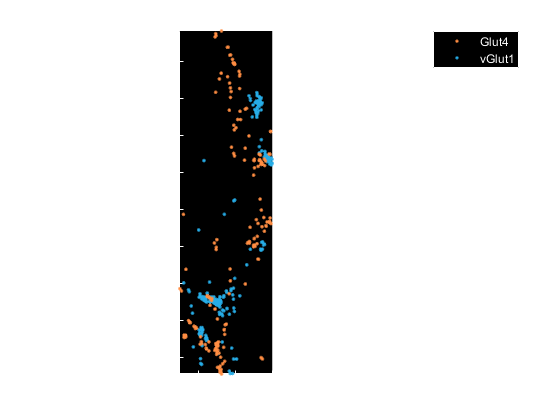

plot3(cdata.red.yf(ind),cdata.red.zf(ind),cdata.red.xf(ind),'.')
zf = cdata.orange.zf;
hold on
plot3(yf(ind_o),zf(ind_o),xf(ind_o),'.')
legend('Glut4','vGlut1')
% axis equal
hold off
% xlim([7 12])
axis equal
xlim([7 12])
midz = (max(zf) + min(zf))/2;
ylim([midz - 2.5, midz + 2.5])
view([0, 00])
xlabel('Microns')
ylabel('(z-axis) Microns')
hold off

%gif('fixed_neruon_vglut_glut4_cell10_.gif','DelayTime', 0.03)
clear M
% M(1) = getframe(gcf);
% for i = 1:2:359
%     view([i,0])
%     M(numel(M)+1) = getframe(gcf)
% end
% movie2gif(M,'rotating_vglut_glut4.gif','DelayTime',0.03,'LoopCount',Inf)
% gif('fixed_neruon_vglut_glut4_cell10_.gif','DelayTime', 0.03)
% for i = 1:359
%     view([i,90])
%     gif()
% end

function indexes = get_index_from_ruler(ruler, image_stack)
    [m,n,o] = size(image_stack);
    [m,n,r] = size(ruler);
    indexes = zeros(o,1);
    for i = 1:o % loop over images
        C = [];
        for j = 1:r
           C(j) = corr2(ruler(:,:,j), image_stack(:,:,i));  
        end
        
        indexes(i) = find(C == max(C));

    end
end

function indexes = get_index_from_quartile_average(ruler, image_stack)
    [m,n,o] = size(image_stack);imagesc(mean(image(:,:,1:2:end),3))
    [m,n,r] = size(ruler);
    indexes = zeros(o,1);
    for i = 1:o % loop over images
        C1 = zeros(r,1);
        C2 = zeros(r,1);
        C3 = zeros(r,1);
        C4 = zeros(r,1);
        % Quartile the image
        image_quarter_1 = image_stack(1:round(m/2),1:round(n/2),i);
        image_quarter_2 = image_stack(round(m/2):m,1:round(n/2),i);
        image_quarter_3 = image_stack(round(m/2):m,round(n/2):n,i);
        image_quarter_4 = image_stack(1:round(m/2),round(n/2):n,i);
        
        for j = 1:r
            % Quartile ruler
            ruler1 = ruler(1:round(m/2),1:round(n/2),j);
            ruler2 = ruler(round(m/2):m,1:round(n/2),j);
            ruler3 = ruler(round(m/2):m,round(n/2):n,j);
            ruler4 = ruler(1:round(m/2),round(n/2):n,j);
            
            C1(j) = corr2(ruler1, image_quarter_1);  
            C2(j) = corr2(ruler2, image_quarter_2);
            C3(j) = corr2(ruler3, image_quarter_3);
            C4(j) = corr2(ruler4, image_quarter_4);
            
        end
        ind(1) = find(C1 == max(C1));
        ind(2) = find(C2 == max(C2));
        ind(3) = find(C3 == max(C3));
        ind(4) = find(C4 == max(C4));
        indexes(i) = mean(ind);
    end
end